## Tutorial 3: Modeling seismic and interseismic behavior of frictional asperities

Lay (1980) proposed a conceptual framework for the slip behavior of heterogeneous faults: earthquakes takes place on unstable asperities, embedded in a stable or conditionally stable fault, as shown in the figure below.

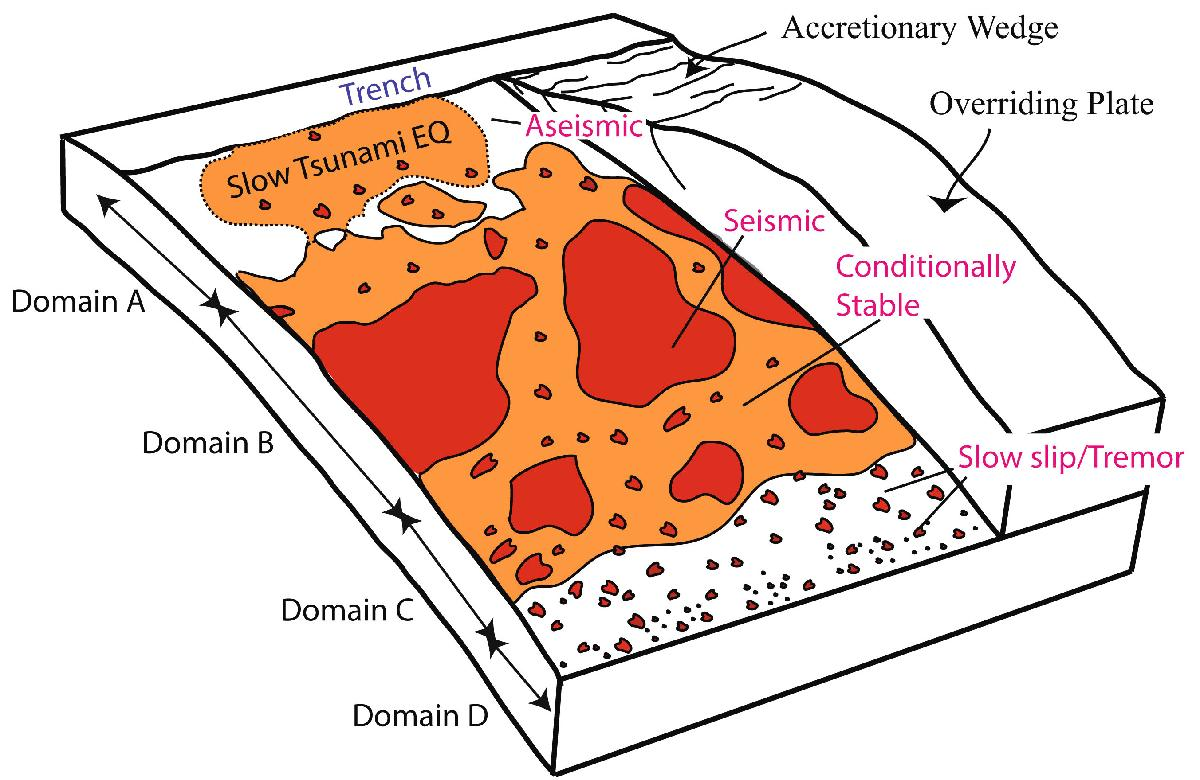

In the context of of rate-state friction, frictional heterogeneities can be interpreted as "velocity-weakening" patches embedded in a "velocity strenghtening" fault (as explained below, these terms refer to the velocity dependence of the friction coefficient at steady-state); alternatively, spatial variations in nucleation length on the fault can give rise to unstable patches embedded in a conditionally stable fault.

Note that this is only one possible interpretation of asperities, and many other properties including stress state and hydrological heterogeneity could modulate slip stability and generate confined stick-slip behavior: even though we only consider rate-state friction in this tutorial, keep in mind that additional effects are at play in nature.

The frictional resistance is given by: 

$\tau =\left(\sigma -p\right)\left\lbrack \mu_0 +\;a\;\log \left(\frac{V}{V_0 }\right)+b\;\log \left(\frac{\theta \;V_0 }{D_c }\right)\right\rbrack$, 

where $\sigma \;$ is the normal stress, p the pore fluid pressure, $V_0 ,\mu_0 ,a,b\;\textrm{and}\;d_c$, are rate-state parameters (see figure below); $\theta$ is the state parameter, which evolves according to the aging law: $\theta^˙ =1-\frac{\theta \;V}{d_c }$. You can find frictional parameters in the file "fs_asp.m". While most parameters reflect realistic fault conditions, others have been chosen with an eye for computational efficiency - see note at the end of the tutorial for more discussion.

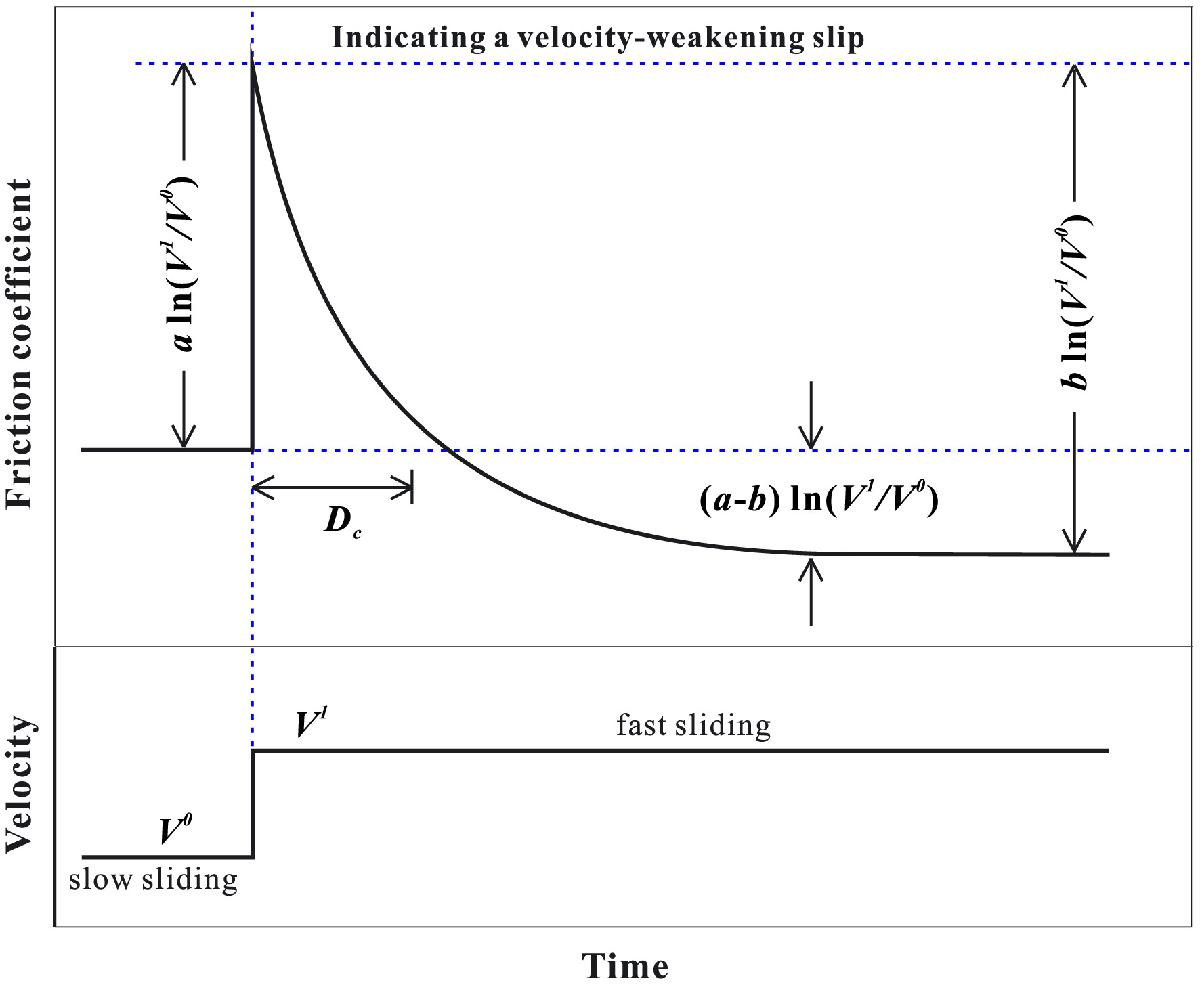

Stick-slip behavior can take place if the steady-state friction coefficient decreases with sliding velocity, which corresponds to the condition: *b>a* (refer to the figure above to see why this is the case). Morever, the size of a sliding fault patch needs to exceed a nucleation radius:


$$L_{\textrm{nuc}} =f\left(a,b\right)\;\frac{G^{\prime } D_c }{\sigma \;},$$


where G' is the shear modulus (antiplane strain) or G/(1-$\left.\nu \right)$with $\nu$ Poisson's ratio in plane strain.  

We will run earthquake cycle simulations using a simplified version of  the quasi-dynamic boundary element code FDRA (Segall and Bradley, 2012). The model is a 2D, plane-strane fault in a homogeneous fullspace, loaded at a constant and uniform shear stressing rate.

First, let's set things up:

% Setup up paths 
path(path,'input');
path(path,'util');
shorthands

% Depending on your machine, you may or may not be able to compile mex
% files needed for fast computation. (If you're not on Linux, you may need
% to use a non-standard C compiler to make it work). Let's test this:
ok = testmex();


You will work in two groups, one looking at a lithological constrast between velocity weakening/velocity strengthening friction ("model 1") , and one looking at spatial variations in nucleation length on a velocity weakening fault ("model 3"). The latter simulation runs faster and it may be preferrable if you couldn't compile mex files above (ok=0).

% Run fs_asp(N) to make a structure containing model parameters, where
% N=[0,1].
%
% You have several options:
% (A) model=0 is a simulation of a single VW asperity in a VS fault. It should 
% only takes few seconds to run. 
% We won't use it, but it's provided as an option if everything else is too slow.
% (B) model=1 is a simulation of 3 VW asperities in a VS fault. It
% should take around 1 minute on a standard laptop.
% (C) model=2: single asperity, like model 0. The asperity is a high normal stress
% patch surrounded by regions of low normal stress.
% (D) model=3: 3 asperities as in model 1, with normal stress contrast as in model 2.

% Choose 1 or 3.
model = 1;

% Set up simulation
f=fs_asp(model);
f.allow_overwrite=1;
%Run simulation
tic; fdra(f); exec_time = toc;
disp(['Simulation ran in ' num2str(toc) 'seconds.']);

%Load simulation
q=qload(f.saveFn);  %Load simulation


Next we look at the simulation input and output

figure
for i=0:1
  %Color plot of slip velocity
  View(q,struct('subplot',[4 2 [1 3]+i],'truetime',i));
  plotasp(q); %add vertical lines for asperities
  if i==0 colorbar off;
  else plotrups(q);
  end
  subplot(4,2,5+i)
  %Plot frictional parameters (a-b):
  stairs(q.xkm, q.c.a-q.c.b,'LineWidth',2);
  hold on; lineyk(0);
  ylim([-1 1]*1e-2)
  xlabel('Distance (km)')
  ylabel('a-b')
  subplot(4,2,7+i)
  stairs(q.xkm, q.c.s_normal/1e6,'LineWidth',2);
  hold on; lineyk(0);
  ylim([0.8*min(q.c.s_normal(1)) 1.2*max(q.c.s_normal)]/1e6)
  xlabel('Distance (km)')
  ylabel('Normal stress \sigma (MPa)')
end


#### *0.1 Qualitatively describe earthquake cycle behavior.*

Identify asperities and qualitatively describe what you seen in terms of (1) seismic behavior; (2) interseismic fault coupling.  Look at the spatial distribution of slip velocities early in the cycle (when some regions are creeping and others are locked). What controls this spatial pattern and its subsequent evolution?

To interpret the figures correctly, compare the slip velocities in the figures above to typical values for plate rate, slow slip events, and earthquakes. Refer back to this figure to interpret your results throughout the tutorial.

**Answer**:

## Part 1: View from the far field

Here we will assume that the asperities are far offshore, and you don't have any geodetic or seismic instrument near them. However, you measure surface displacement in the far-field which allows you to estimate *average* slip velocities. You want to estimate the seismic potential of this fault section by looking at the interseismic slip deficit, quantified by the interseismic coupling coefficient:

$\chi_I \;=1-\frac{V}{V_{\textrm{pl}} }$,

where V is the slip velocity along the interface and Vpl the plate velocity.

#### *1.1 Assuming a plate velocity of 10mm/yr, look at interseismic coupling as a function of time.*

How does plate coupling evolve throughout the seismic cycle? Is the fault ever fully locked or fully uncoupled? Comment on how the maximum observed value of interseismic coupling is related to frictional heterogeneity (for example, describe how coupling would change if you have smaller or larger asperities).

% Write your code here.
% A couple of pointers:
% Time is stored in q.t (seconds). Multiply by sec2year to convert.
% Slip velocity is stored in q.v (m/s) such that q.v(i,j) gives you
% is the slip velocity at grid point i, time j.


**Answer: **

#### *1.2 Repeat the previous analysis separately for asperities and non-asperities.*

How does interseimic coupling evolves throughout the cycle in each case? Identify trends in interseimic coupling (increase/decrease) and explain them.

Is the time-dependent pattern of interseismic coupling consistent with any observation you heard about in lectures? If so, list relevant examples.

%Write your code here

**Answer: **

## Part II - Estimating future earthquakes from coupling maps.

Now we consider a case with better near-field monitornig, that allows us to image fault slip more accureately and obtain coupling maps. Imagine that you have no information about past rupture history, and you want to estimate future ruptures based on single "snapshots" of interseismic coupling. In this part of the tutorial you will test the reliability of this method and think about the implicit assumptions.

***2.1 Estimating asperity dimension***

Choose few points in time between large earthquakes (mainshocks on the largest asperity), at various fractions of the seismic cycle. Plot slip velocity profiles, and use them to estimate the size of seismic asperities; it doesn't need to be extremely accurate (you can do it by eye).

Once you have estiamated the radius of both asperities copy it in this shared file:

https://docs.google.com/spreadsheets/d/1Eyz5wDKsgyumc74o-sYhd0IWEZCipsjwlye2BcnxuBo/edit?usp=sharing

% The following function returns indices of earthquake timesteps 
% (start of each event), from which we get earthquake times. Use these to
% choose various points in time between two earthquakes.
eqks = find_eqks(q);
eq_t = q.t(eqks);

%Write your code here



***2.2 Estimating earthquake magnitudes***

Once everyone is done, copy all the values into a file and load it here. Calculate seismic moments and magnitudes from all estimated values of asperity radii. To estimate seismic moment, assume that future earthquakes will occur have a uniform stress drop across a circle of radius R, and use the following formula:


$$M_0 =\frac{16}{7}\Delta \tau \;R^3$$


Convert this to moment magnitude and plot your estimates as a function of time (or time normalized by seismic cycle duration).

How accurate are the magnitude estimates compared to (1) the true asperity dimension, and (2) simulated earthquakes? What assumptions are implicit in this method, and are they reasonable assumptions? Comment on the origin of any discrepancy between magnitude estimates from interseismic coupling and actual earthquake magnitudes in the simulations

%Write your code here. Use the matlab command "load" to load the file.


**Answer: **

***2.3 Putting it all together: comparison between rate-state vs. normal stress heterogeneity***

In what ways are the two models of heterogeneity similar or different? How can they be distinguished from interseismic data?

**Answer: **

***2.4 Bonus question (if there is time)***

There is a smaller asperity on the right. How does its slip behavior differ from the other two, and why?

**Answer**:

**A note on frictional parameters used in the simulations**. To keep computational costs reasonable, here we employed a large slip weakening distance Dc (3cm, as opposed to typical laboratory values <10$\mu$m). This leads to large characteristic lengthscales: nucleation length and cohesive zone at the crack tip, so that we can use a large grid spacing and reduce run time. The large nucleation length enables extended creep in velocity weakening regions seen in these examples. With realistic Dc values, rate-state friction alone is unlikely to produce this behavior; however, other stabilizing mechanisms (such as fault dilatancy (Segall and Rice, 2010), or a transition to rate-state friction during slip ), may also increase fault stability and produce similar behavior. The exact physical processes responsible for transient changes in seismic coupling remains largely an open question.

Due to the large nucleation dimension, the simulations in this tutorial have a small ratio: R/Lnuc (where R is the asperity radius and Lnuc the nucleation radius); in this regime, asperities always produce full ruptures. A smaller, and more realistic, Dc inrcease would increase R/Lnuc and enable partial ruptures (Cattania, 2019); 

**References:**

Cattania, Camilla. 2019. “Complex Earthquake Sequences on Simple Faults.” *Geophysical Research Letters* 46 (3). [https://doi.org/10.1029/2019GL083628](https://doi.org/10.1029/2019GL083628).

Dieterich, J. H. 1979. “Modeling of Rock Friction: 1. Experimental Results and Constituve Equations.” *Journal of Geophysical Research* 84 (9): 2161–68. [https://doi.org/10.1007/BF00876539](https://doi.org/10.1007/BF00876539).

Johnson, Kaj M., Jun’Ichi Fukuda, and Paul Segall. 2012. “Challenging the Rate-State Asperity Model: Afterslip Following the 2011 M9 Tohoku-Oki, Japan, Earthquake.” *Geophysical Research Letters* 39 (20). [https://doi.org/10.1029/2012GL052901](https://doi.org/10.1029/2012GL052901).

Johnson, Kaj M., Andreas Mavrommatis, and Paul Segall. 2016. “Small Interseismic Asperities and Widespread Aseismic Creep on the Northern Japan Subduction Interface.” *Geophysical Research Letters* 43: 135–43. [https://doi.org/10.1002/2015GL066707](https://doi.org/10.1002/2015GL066707).    

Lay, Thorne, and Hiroo Kanamori. 1980. “An Asperity Model of Large Earthquake Sequences.” *Earthquake Prediction: An International Review* 4: 579–92.

Segall, Paul, and Andrew M Bradley. 2012. “The Role of Thermal Pressurization and Dilatancy in Controlling the Rate of Fault Slip.” *J. Applied Mech.* 79 (3): 31013. [https://doi.org/10.1115/1.4005896](https://doi.org/10.1115/1.4005896).

Segall, Paul, Allan M. Rubin, Andrew M. Bradley, and James R. Rice. 2010. “Dilatant Strengthening as a Mechanism for Slow Slip Events.” *Journal of Geophysical Research: Solid Earth* 115 (12). [https://doi.org/10.1029/2010JB007449](https://doi.org/10.1029/2010JB007449).